clc; clear; close all

imu_cal_data_with_table = importdata("imu_cal_data_with_table.txt")

imu_cal_data_with_table = 1.0e+04 *

                   0  -0.000008134889754  -0.000016509040970   0.001459734187839   0.000254825665675  -0.000006103608759  -0.000122072175174   0.033400000000000   6.552800000000000   6.537600000000000                   0   0.009799021875000   0.003458933258057
   0.000004600000000  -0.000006938582437  -0.000005742275120   0.001453274128328   0.000236514839399   0.000012970168612   0.000018310826276   0.031000000000000   0.001700000000000   0.002400000000000                   0   0.009799021875000   0.003458933258057
   0.000009200000000  -0.000002392614633  -0.000009570458534   0.001458298619059   0.000204470893416   0.000016021972992   0.000072480354009   0.026800000000000   0.002100000000000   0.009500000000000                   0   0.009798726562500   0.003458005905151
   0.000013800000000  -0.000000717784390  -0.000009091935607   0.001461648279545   0.000231937132830   0.000016021972992   0.000038910505837   0.030400000000000   0.002100000000000

imu_cal_data_with_table_int = importdata("imu_cal_data_with_table_int.txt")

imu_cal_data_with_table_int = 1.0e+04 *

                   0   6.540000000000000   6.526000000000000   2.440400000000000   0.033400000000000   6.552800000000000   6.537600000000000   0.033400000000000   6.552800000000000   6.537600000000000                   0   0.009799021875000   0.003458933258057
   0.000004600000000   6.542000000000000   6.544000000000000   2.429600000000000   0.031000000000000   0.001700000000000   0.002400000000000   0.031000000000000   0.001700000000000   0.002400000000000                   0   0.009799021875000   0.003458933258057
   0.000009200000000   6.549600000000000   6.537600000000000   2.438000000000000   0.026800000000000   0.002100000000000   0.009500000000000   0.026800000000000   0.002100000000000   0.009500000000000                   0   0.009798726562500   0.003458005905151
   0.000013800000000   6.552400000000000   6.538400000000000   2.443600000000000   0.030400000000000   0.002100000000000   0.005100000000000   0.030400000000000   0.00210000000

imu_data_int = importdata("imu_data_int.txt")

imu_data_int = 1.0e+04 *

                   0   6.540400000000000   0.019600000000000   2.438400000000000   0.018200000000000   6.548800000000000   6.457800000000000   0.018200000000000   6.548800000000000   6.457800000000000                   0   0.009776332031250   0.003591519546509
   0.000004600000000   0.019600000000000   6.450400000000000   2.430400000000000   0.022000000000000   0.003700000000000   6.464400000000000   0.022000000000000   0.003700000000000   6.464400000000000                   0   0.009775945312500   0.003589665222168
   0.000009200000000   6.542400000000000   6.550000000000000   2.433200000000000   0.029700000000000   6.552100000000000   6.545300000000000   0.029700000000000   6.552100000000000   6.545300000000000                   0   0.009776343750000   0.003591055679321
   0.000013800000000   6.544000000000000   6.533200000000000   2.442400000000000   0.030400000000000   0.003200000000000   6.550600000000000   0.030400000000000   0.003200000000000   6.550600

imu_data_units = importdata("imu_data_units.txt")

imu_data_units = 1.0e+04 *

                   0  -0.000007895628290   0.000011723811704   0.001458537880522   0.000138857099260  -0.000036621652552  -0.000730907148852   0.018200000000000   6.548800000000000   6.457800000000000                   0   0.009776332031250   0.003591519546509
   0.000004600000000   0.000011723811704  -0.000061729457542   0.001453752651255   0.000167849240864   0.000028229190509  -0.000680552376593   0.022000000000000   0.003700000000000   6.464400000000000                   0   0.009775945312500   0.003589665222168
   0.000009200000000  -0.000006699320974  -0.000002153353170   0.001455427481498   0.000226596475166  -0.000011444266423  -0.000063324940871   0.029700000000000   6.552100000000000   6.545300000000000                   0   0.009776343750000   0.003591055679321
   0.000013800000000  -0.000005742275120  -0.000012202334630   0.001460930495155   0.000231937132830   0.000024414435035  -0.000022888532845   0.030400000000000   0.003200000000000   6.5506


% x red
% y green
% z blue

Figure 1: Raw Data without Rig

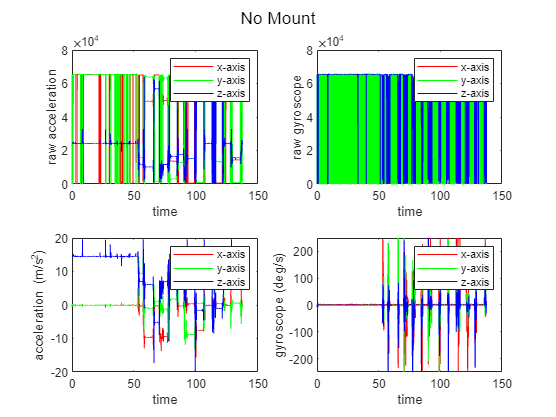

figure
subplot(2,2,1)
plot(imu_data_int(:,1),imu_data_int(:,2),'r')
hold on
plot(imu_data_int(:,1),imu_data_int(:,3),'g')
plot(imu_data_int(:,1),imu_data_int(:,4),'b')
xlabel('time');ylabel('raw acceleration')
legend('x-axis','y-axis','z-axis')

subplot(2,2,2)
plot(imu_data_int(:,1),imu_data_int(:,5),'r')
hold on
plot(imu_data_int(:,1),imu_data_int(:,6),'g')
plot(imu_data_int(:,1),imu_data_int(:,7),'b')
xlabel('time');ylabel('raw gyroscope')
legend('x-axis','y-axis','z-axis')

% figure('Name','Computed Data - No Mount')
subplot(2,2,3)
plot(imu_data_units(:,1),imu_data_units(:,2),'r')
hold on
plot(imu_data_units(:,1),imu_data_units(:,3),'g')
plot(imu_data_units(:,1),imu_data_units(:,4),'b')
xlabel('time');ylabel('acceleration (m/s^2)')
legend('x-axis','y-axis','z-axis')

subplot(2,2,4)
plot(imu_data_units(:,1),imu_data_units(:,5),'r')
hold on
plot(imu_data_units(:,1),imu_data_units(:,6),'g')
plot(imu_data_units(:,1),imu_data_units(:,7),'b')
xlabel('time');ylabel('gyroscope (deg/s)')
legend('x-axis','y-axis','z-axis')

sgtitle('No Mount')

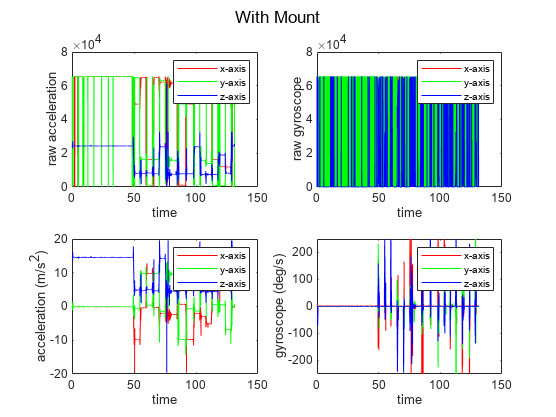


figure
subplot(2,2,1)
plot(imu_cal_data_with_table_int(:,1),imu_cal_data_with_table_int(:,2),'r')
hold on
plot(imu_cal_data_with_table_int(:,1),imu_cal_data_with_table_int(:,3),'g')
plot(imu_cal_data_with_table_int(:,1),imu_cal_data_with_table_int(:,4),'b')
xlabel('time');ylabel('raw acceleration')
legend('x-axis','y-axis','z-axis')

subplot(2,2,2)
plot(imu_cal_data_with_table_int(:,1),imu_cal_data_with_table_int(:,5),'r')
hold on
plot(imu_cal_data_with_table_int(:,1),imu_cal_data_with_table_int(:,6),'g')
plot(imu_cal_data_with_table_int(:,1),imu_cal_data_with_table_int(:,7),'b')
xlabel('time');ylabel('raw gyroscope')
legend('x-axis','y-axis','z-axis')

% figure('Name','Computed Data - With Mount')
subplot(2,2,3)
plot(imu_cal_data_with_table(:,1),imu_cal_data_with_table(:,2),'r')
hold on
plot(imu_cal_data_with_table(:,1),imu_cal_data_with_table(:,3),'g')
plot(imu_cal_data_with_table(:,1),imu_cal_data_with_table(:,4),'b')
xlabel('time');ylabel('acceleration (m/s^2)')
legend('x-axis','y-axis','z-axis')

subplot(2,2,4)
plot(imu_cal_data_with_table(:,1),imu_cal_data_with_table(:,5),'r')
hold on
plot(imu_cal_data_with_table(:,1),imu_cal_data_with_table(:,6),'g')
plot(imu_cal_data_with_table(:,1),imu_cal_data_with_table(:,7),'b')
xlabel('time');ylabel('gyroscope (deg/s)')
legend('x-axis','y-axis','z-axis')

sgtitle('With Mount')